clear; close all; clc;

## Setup (using your existing parameters)

mm = 1000;
f = 1200; % Hz
c = 343.3; % Speed of sound [m/s]
lambda = c / f

lambda = 0.2861

point_distance = 0.01; % m
array_length_m = 1210 / mm;
No_linearray_elements = 6;
points_per_element = round((array_length_m / point_distance) / No_linearray_elements);

N_hor = 600;
N_ver = N_hor;
array_length = round(array_length_m / point_distance);
array_start = round((N_ver - array_length) / 2);
array_end = round((N_ver + array_length) / 2);

## Define array geometry

element_spacing = array_length_m / No_linearray_elements

element_spacing = 0.2017

element_positions = zeros(No_linearray_elements, 1);
for i = 1:No_linearray_elements
    element_positions(i) = (i - 0.5) * element_spacing - array_length_m/2;
end

array_geometry.element_positions = element_positions;
array_geometry.points_per_element = points_per_element;
array_geometry.point_distance = point_distance;
array_geometry.array_length = array_length_m;

## Simulation parameters

simulation_params.point_distance = point_distance;
simulation_params.N_hor = N_hor;
simulation_params.N_ver = N_ver;
simulation_params.No_linearray_elements = No_linearray_elements;
simulation_params.points_per_element = points_per_element;
simulation_params.array_start = array_start;
simulation_params.array_end = array_end;


## Optimization parameters (default values - adjust as needed)

optimization_params.mainlobe_width_deg = 5;
optimization_params.desired_beamwidth_deg = 25;
optimization_params.gain_uniformity_weight = 0.01;
optimization_params.total_gain_constraint = No_linearray_elements * 0.5;

optimization_params.weights.steering = 40; % 100;
optimization_params.weights.target_response = 40; % 60;
optimization_params.weights.sidelobe = 220 ;% 450
optimization_params.weights.beamwidth = 0.06; %1; % 0.5;
optimization_params.weights.gain_variation = 0.1; %0.1; % 0.1;

Generate frequencies

angles = linspace(90,-90,80);
DI_matrix = zeros(length(angles));
delay_matrix = zeros(length(angles), No_linearray_elements);
gain_matrix = zeros(length(angles), No_linearray_elements);
delay_func_coeffs_matrix = zeros(50,2);

f_idx = 1;
for f = logspace(2.69,3.6,50)
    
    for idx = 1:length(angles)
        [delay_matrix(idx,:), gain_matrix(idx,:), result] = optimize_beam_steering(...
        angles(idx), f, array_geometry, optimization_params);
        DI_matrix(idx) = result.directivity_index;
    end
    delay_func_coeffs = delay_optimization(angles, delay_matrix);
    delay_func_coeffs_matrix(f_idx,:) = [delay_func_coeffs.max_delay, delay_func_coeffs.stretch];
    %smooth_curve = delay_func_coeffs.max_delay * tanh(delay_func_coeffs.stretch * angles);
    %max_delays = delay_func_coeffs.max_delay * ((1:No_linearray_elements) - 0.5 - No_linearray_elements/2)/(No_linearray_elements/2 - 0.5);
    f_idx = f_idx + 1;
end

delay_func_coeffs_matrix

delay_func_coeffs_matrix =     0.0015    0.0189
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


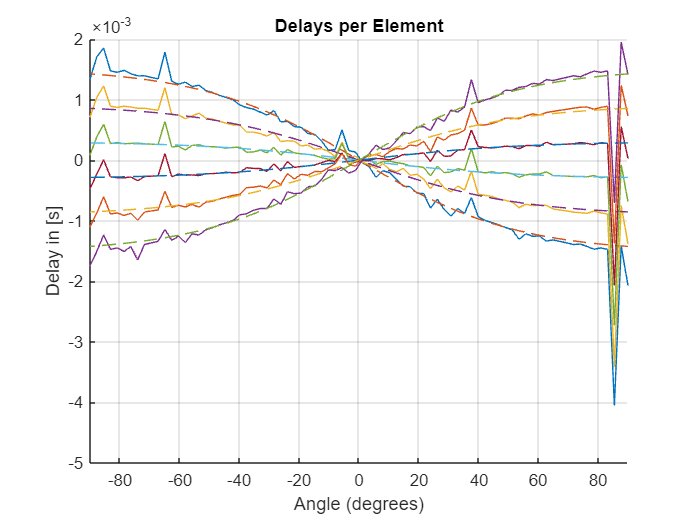

figure;
hold on
max_delays = delay_func_coeffs.max_delay * ((1:No_linearray_elements) - 0.5 - No_linearray_elements/2)/(No_linearray_elements/2 - 0.5);
for ii = 1:No_linearray_elements
 plot(angles,delay_matrix(:,ii)')
 smooth_curve = max_delays(ii) * tanh(delay_func_coeffs.stretch * angles);
 plot(angles,smooth_curve,"--")
end
grid on;
xlabel('Angle (degrees)');
ylabel('Delay in [s]');
title('Delays per Element');
xlim([-90 90]);

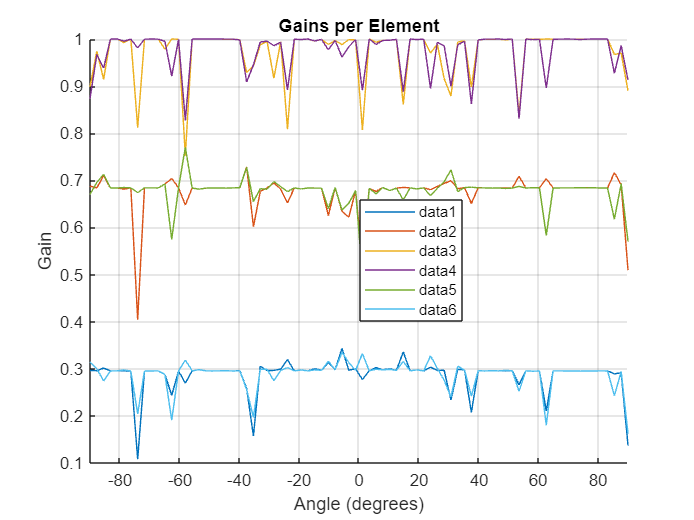


figure;
hold on
for ii = 1:No_linearray_elements
 plot(angles,gain_matrix(:,ii)')
end
grid on;
xlabel('Angle (degrees)');
ylabel('Gain');
title('Gains per Element');
xlim([-90 90]);

legend("Position", [0.51889,0.3847,0.14769,0.23197])

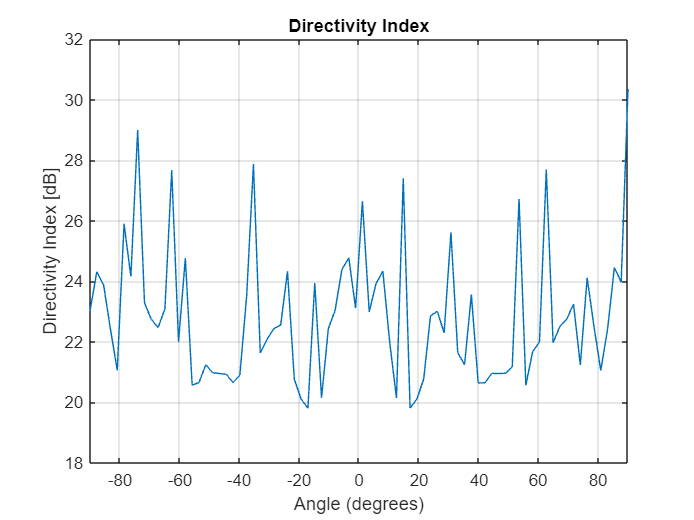


figure;
plot(angles,DI_matrix(:,1)')
grid on;
xlabel('Angle (degrees)');
ylabel('Directivity Index [dB]');
title('Directivity Index');
xlim([-90 90]);